clear
sensor_pin = 'A5';
pan_pin = 'D9';
tilt_pin = 'D10';



% a = arduino();
a = arduino('/dev/tty.usbmodem144201', 'Uno', 'Libraries', 'Servo');

pan_servo = servo(a,pan_pin,"MinPulseDuration",700*10^-6,'MaxPulseDuration',2300*10^-6);
tilt_servo = servo(a,tilt_pin,"MinPulseDuration",700*10^-6,'MaxPulseDuration',2300*10^-6);

%move servo to middle position for next scan

writePosition(pan_servo,Deg2Pos(0));
writePosition(tilt_servo,Deg2Pos(0));

% initilize pan and tilt servo to upper left corner of scan image
count = 1;
points = [];
for tilt_angle = -30:2:30
    disp(tilt_angle);
    writePosition(tilt_servo,Deg2Pos(tilt_angle));
    pause(0.1);
    for pan_angle = -30:2:30
        disp(pan_angle);
        writePosition(pan_servo,Deg2Pos(pan_angle));
        %take a scan here for each step
        points= [points,get_coordinates(a,pan_angle,tilt_angle)];
        count = count + 1;
        pause(0.1);
    end

end

   -30



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14



Error using get_coordinates
Unable to receive data from the target hardware.
 For MATLAB, reconnect the target hardware, clear the hardware objects and try again.
 For Simulink, reconnect the target hardware and start simulation again.

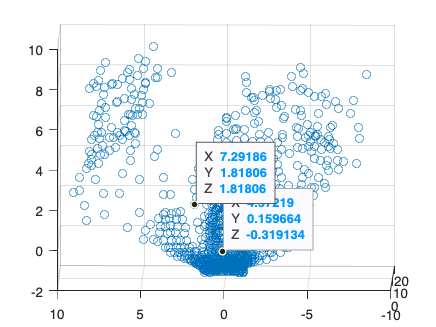

clf
x = points(1,:);
y = points(2,:);
z = points(3,:);
scatter3(x,z,y)

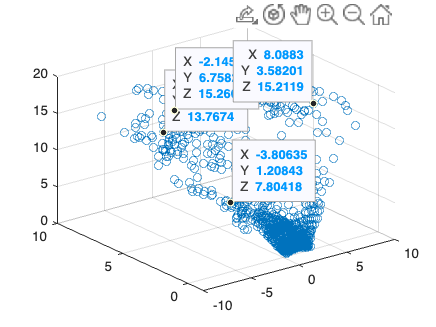

clf
z = points(1,:);
y = points(2,:);
x = points(3,:);
scatter3(x,y,z)

disp(points);



function pos = Deg2Pos(degree)
% degree ranges from -90 to 90
pos = 0.5+degree/180;
end

function distance = get_distance(voltage)
distance = 18.9*exp(-0.7578*voltage);
end 
